## PART 2: Trajectory Planning 

In this part, the goal is to plan a trajectory which approximates the circular path from Problem 3 by means of 5 knot-points at *ϕ*0, *ϕ*9, *ϕ*18, *ϕ*27, *ϕ*36. 

### Problem 6:

Use the inverse computed joint confifigurations *q *(0) , *q *(9) , *q *(18) , *q *(27) , *q *(36) from Problem 3, to fifind suitable interpolation polynomials for the following segments: 

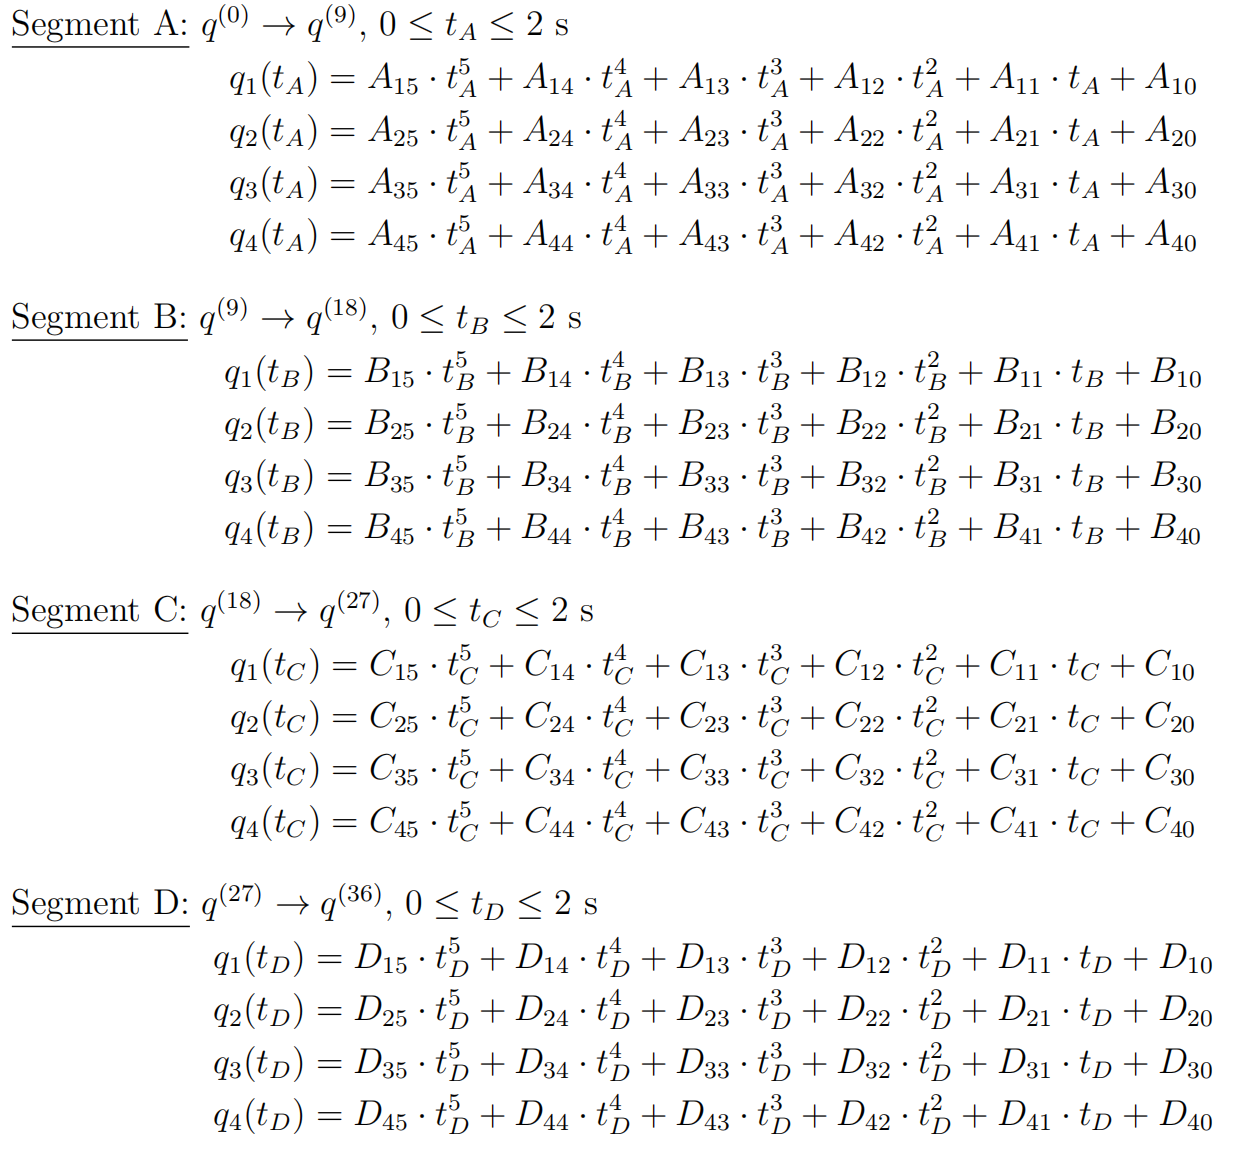

Determine the coeffiffifficients *A**ij *, *B**ij *, *C**ij *, *D**ij *so that 

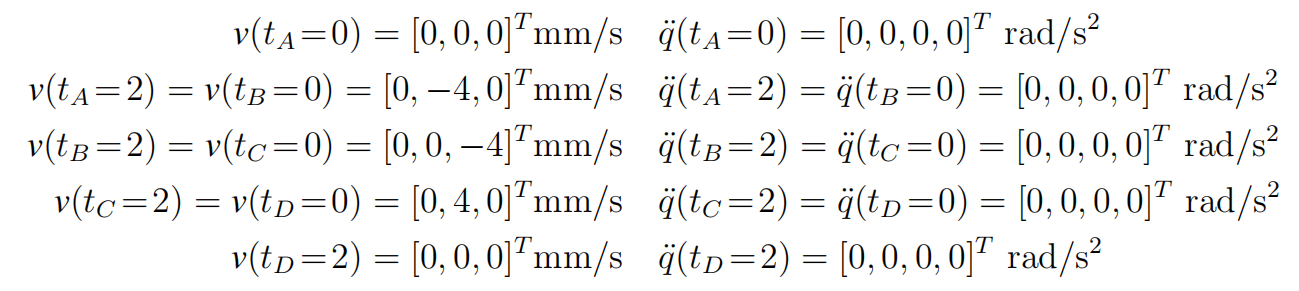

Hint: Note that end-effffector velocities *v *need to be converted to joint velocities ˙*q *and that requiring zero joint acceleration at knot points is maybe not the best but the simplest option. 

load("t1.mat");
load("t2.mat");
load("t3.mat");
load("t4.mat");

tIN = 0;%start point of each time interval
tOUT = 2;%end point of each time interval
MatrixofQ = [t1(1) t1(10) t1(19) t1(28) t1(37);
             t2(1) t2(10) t2(19) t2(28) t2(37);
             t3(1) t3(10) t3(19) t3(28) t3(37);
             t4(1) t4(10) t4(19) t4(28) t4(37)];%t(1), t(10), t(19), t(28), t(37) is
                                                %relative to q(0), q(9), q(18), q(27), q(36)
V0 = [0;0;0];
VA = [0;-4;0];
VB = [0;0;-4];
VC = [0;4;0];
VD = [0;0;0];
%vectors of end-effffector velocities v 
JA = getJacobian(10);

o04 =  -173.2162
         0
   48.2785


o14 =  -173.2162
         0
   48.2785


o24 =   -89.1045
  148.5503
         0


o34 =    92.3358
 -234.9552
         0


J =          0  -48.2785         0         0
 -173.2162         0         0         0
         0 -173.2162  -89.1045   92.3358


JB = getJacobian(19);

o04 =  -163.2115
         0
  -28.8473


o14 =  -163.2115
         0
  -28.8473


o24 =  -123.0441
  133.0979
         0


o34 =   123.1004
 -267.9202
         0


J =          0   28.8473         0         0
 -163.2115         0         0         0
         0 -163.2115 -123.0441  123.1004


JC = getJacobian(28);

o04 =  -167.1672
         0
   27.0025


o14 =  -167.1672
         0
   27.0025


o24 =  -111.6978
  126.4807
         0


o34 =   106.1632
 -248.9397
         0


J =          0  -27.0025         0         0
 -167.1672         0         0         0
         0 -167.1672 -111.6978  106.1632


JD = getJacobian(37);

o04 =  -156.6301
         0
   91.1506


o14 =  -156.6301
         0
   91.1506


o24 =   -77.2531
  142.3317
         0


o34 =    78.2293
 -220.6250
         0


J =          0  -91.1506         0         0
 -156.6301         0         0         0
         0 -156.6301  -77.2531   78.2293


%jaconbian matrix for calculating joint velocities ˙q
v0=0;
vA=JA/VA;

Error using  / 
Matrix dimensions must agree.

vB=JB/VB;
vC=JC/VC;
vD=JD/VD;
%Calculation of joint velocities ˙q
ain = 0;
aout = 0;
%acceleration is always 0

A1 = getConstant(tIN,tOUT,MatrixofQ(1,1),MatrixofQ(1,2),v0,vA,ain,aout);
A2 = getConstant(tIN,tOUT,MatrixofQ(2,1),MatrixofQ(2,2),v0,vA,ain,aout);
A3 = getConstant(tIN,tOUT,MatrixofQ(3,1),MatrixofQ(3,2),v0,vA,ain,aout);
A4 = getConstant(tIN,tOUT,MatrixofQ(4,1),MatrixofQ(4,2),v0,vA,ain,aout);
A = [A1;A2;A3;A4];

B1 = getConstant(tIN,tOUT,MatrixofQ(1,2),MatrixofQ(1,3),vA,vB,ain,aout);
B2 = getConstant(tIN,tOUT,MatrixofQ(2,2),MatrixofQ(2,3),vA,vB,ain,aout);
B3 = getConstant(tIN,tOUT,MatrixofQ(3,2),MatrixofQ(3,3),vA,vB,ain,aout);
B4 = getConstant(tIN,tOUT,MatrixofQ(4,2),MatrixofQ(4,3),vA,vB,ain,aout);
B = [B1;B2;B3;B4];

C1 = getConstant(tIN,tOUT,MatrixofQ(1,3),MatrixofQ(1,4),vB,vC,ain,aout);
C2 = getConstant(tIN,tOUT,MatrixofQ(2,3),MatrixofQ(2,4),vB,vC,ain,aout);
C3 = getConstant(tIN,tOUT,MatrixofQ(3,3),MatrixofQ(3,4),vB,vC,ain,aout);
C4 = getConstant(tIN,tOUT,MatrixofQ(4,3),MatrixofQ(4,4),vB,vC,ain,aout);
C = [C1;C2;C3;C4];

D1 = getConstant(tIN,tOUT,MatrixofQ(1,4),MatrixofQ(1,5),vC,vD,ain,aout);
D2 = getConstant(tIN,tOUT,MatrixofQ(2,4),MatrixofQ(2,5),vC,vD,ain,aout);
D3 = getConstant(tIN,tOUT,MatrixofQ(3,4),MatrixofQ(3,5),vC,vD,ain,aout);
D4 = getConstant(tIN,tOUT,MatrixofQ(4,4),MatrixofQ(4,5),vC,vD,ain,aout);
D = [D1;D2;D3;D4];
%Calculation of Coefficients in Interpolation Functions

### Problem 7:

Plot the actual path of the end-effector as a function of time for the interpolated trajectory from Problem 6 and its deviation from the desired circular path. Try to improve the approximation either by using more knot-points or by using different interpolation functions than those found in Problem 6.

q1A = A1(6) * x^5 + A1(5) * x^4 + A1(4) * x^3 + A1(3) * x^2 + A1(2) * x + A1(1);
q2A = A2(6) * x^5 + A2(5) * x^4 + A2(4) * x^3 + A2(3) * x^2 + A2(2) * x + A2(1);
q3A = A3(6) * x^5 + A3(5) * x^4 + A3(4) * x^3 + A3(3) * x^2 + A3(2) * x + A3(1);
q4A = A4(6) * x^5 + A4(5) * x^4 + A4(4) * x^3 + A4(3) * x^2 + A4(2) * x + A4(1);

q1B = B1(6) * x^5 + B1(5) * x^4 + B1(4) * x^3 + B1(3) * x^2 + B1(2) * x + B1(1);
q2B = B2(6) * x^5 + B2(5) * x^4 + B2(4) * x^3 + B2(3) * x^2 + B2(2) * x + B2(1);
q3B = B3(6) * x^5 + B3(5) * x^4 + B3(4) * x^3 + B3(3) * x^2 + B3(2) * x + B3(1);
q4B = B4(6) * x^5 + B4(5) * x^4 + B4(4) * x^3 + B4(3) * x^2 + B4(2) * x + B4(1);

q1C = C1(6) * x^5 + C1(5) * x^4 + C1(4) * x^3 + C1(3) * x^2 + C1(2) * x + C1(1);
q2C = C2(6) * x^5 + C2(5) * x^4 + C2(4) * x^3 + C2(3) * x^2 + C2(2) * x + C2(1);
q3C = C3(6) * x^5 + C3(5) * x^4 + C3(4) * x^3 + C3(3) * x^2 + C3(2) * x + C3(1);
q4C = C4(6) * x^5 + C4(5) * x^4 + C4(4) * x^3 + C4(3) * x^2 + C4(2) * x + C4(1);

q1D = C1(6) * x^5 + D1(5) * x^4 + D1(4) * x^3 + D1(3) * x^2 + D1(2) * x + D1(1);
q2D = C2(6) * x^5 + D2(5) * x^4 + D2(4) * x^3 + D2(3) * x^2 + D2(2) * x + D2(1);
q3D = C3(6) * x^5 + D3(5) * x^4 + D3(4) * x^3 + D3(3) * x^2 + D3(2) * x + D3(1);
q4D = C4(6) * x^5 + D4(5) * x^4 + D4(4) * x^3 + D4(3) * x^2 + D4(2) * x + D4(1);
figure; % Create a new figure window
y1 = q1A.*(x>=0&x<=2) + q1B.*(x>2&x<=4) + q1C.*(x>4&x<=6) + q1D.*(x>6&x<=8);
plot(x, y1, 'b');
hold on
y2 = q2A.*(x>=0&x<=2) + q2B.*(x>2&x<=4) + q2C.*(x>4&x<=6) + q2D.*(x>6&x<=8);
plot(x, y2, 'r');
hold on
y3 = q3A.*(x>=0&x<=2) + q3B.*(x>2&x<=4) + q3C.*(x>4&x<=6) + q3D.*(x>6&x<=8);
plot(x, y3, 'g');
hold on
y4 = q4A.*(x>=0&x<=2) + q4B.*(x>2&x<=4) + q4C.*(x>4&x<=6) + q4D.*(x>6&x<=8);
plot(x, y1, 'y'); 
